load uspsDigits.mat;
% fix so is uses the centroid of the training data and check vs the test
% data

% centroid metoden (mot 1 centroid - typ värdelös)
% fix loop and check tempDiff
%ima(testDigits(:,:,1))
randImgIndex = randi(2007)

randImgIndex = 1641

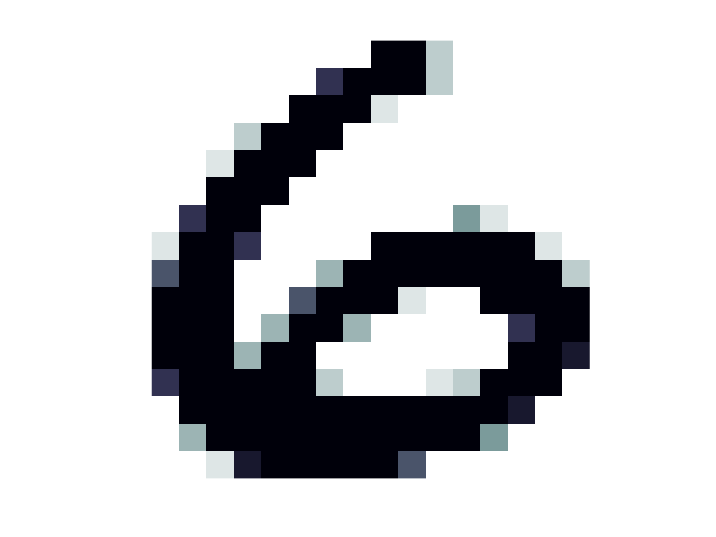

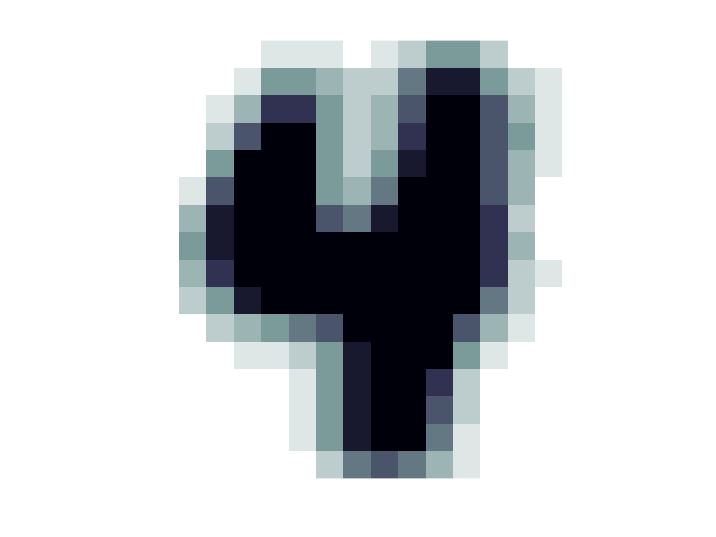


indexDigit = find(testAns == 4);

%mean(testDigits(indexDigit),3)
sumDigit = zeros(16,16,1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,1) = sumDigit(:,:,1) + testDigits(:,:,indexValue);
end
meanDigit = sumDigit./length(indexDigit);
ima(testDigits(:,:,randImgIndex))
ima(meanDigit)


testAns(randImgIndex)

ans = 6

%tempDiff = abs(norm(meanDigit(:,:,1)) - norm(testDigits(:,:,randImgIndex)))
tempDiff = abs(norm(meanDigit(:,:,1) - testDigits(:,:,randImgIndex))) % this is the right one?

tempDiff = 4.7390

% centroid metoden
disp('new part')


new part



randImgIndex = randi(2007)

randImgIndex = 615

results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(testAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        testDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     5.6178
    4.9985
    3.8078
    4.9333
    4.6836
    4.5089
    3.2895
    5.5351
    3.9605
    5.6324


[M,I] = min(results);
minDigit = I-1

minDigit = 6

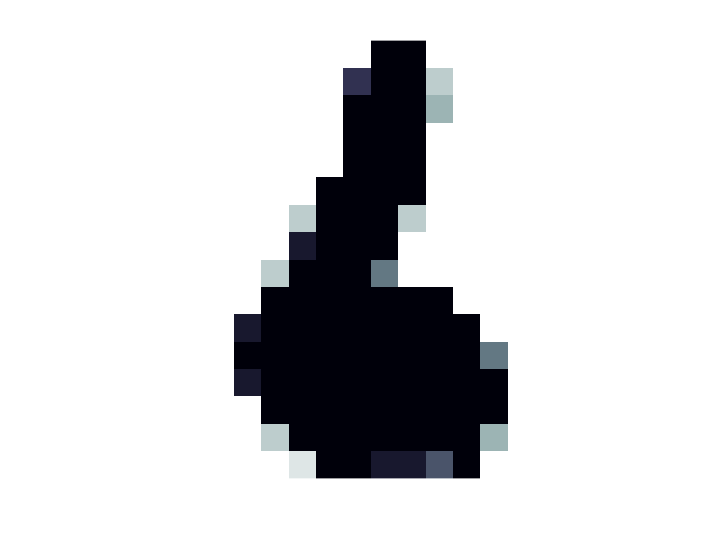

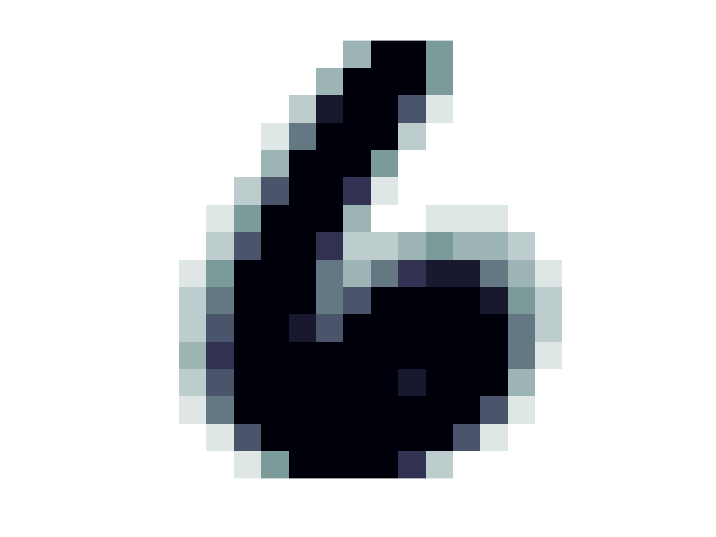

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% closest neighbooooor
disp('new part')


new part



randImgIndex = randi(2007)

randImgIndex = 1021

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 1537

savedDiff

savedDiff = 3.1562

testAns(randImgIndex)

ans = 0

testAns(savedIndex)

ans = 0

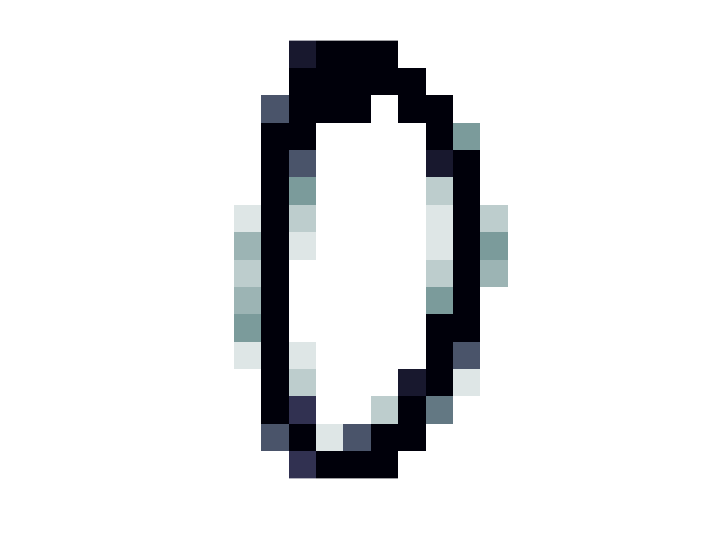

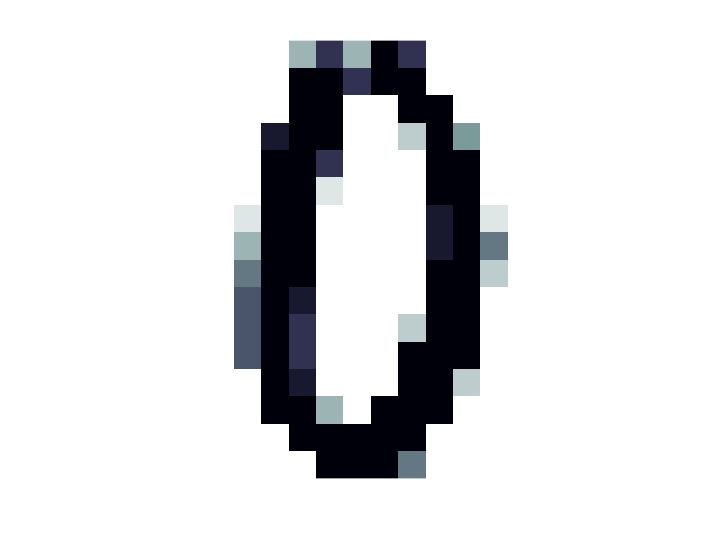

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

% 5 closest neighbooors 
disp('new part')


new part



randImgIndex = randi(2007)

randImgIndex = 1026

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex && c ~= nClosesNeighbooorIndex(1) && c ~= nClosesNeighbooorIndex(2) && c ~= nClosesNeighbooorIndex(3) && c ~= nClosesNeighbooorIndex(4) && c ~= nClosesNeighbooorIndex(5)
            %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
            tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
            %{
            if tempDiff < nClosesNeighbooorValues(1)
                nClosesNeighbooorValues(1) = tempDiff;
                nClosesNeighbooorIndex(1) = c;
            elseif tempDiff < nClosesNeighbooorValues(2)
                nClosesNeighbooorValues(2) = tempDiff;
                nClosesNeighbooorIndex(2) = c;
            elseif tempDiff < nClosesNeighbooorValues(3)
                nClosesNeighbooorValues(3) = tempDiff;
                nClosesNeighbooorIndex(3) = c;
            elseif tempDiff < nClosesNeighbooorValues(4)
                nClosesNeighbooorValues(4) = tempDiff;
                nClosesNeighbooorIndex(4) = c;
            elseif tempDiff < nClosesNeighbooorValues(5)
                nClosesNeighbooorValues(5) = tempDiff;
                nClosesNeighbooorIndex(5) = c;
            end
            %}
            for j = 1:5
                if tempDiff < nClosesNeighbooorValues(j)
                    nClosesNeighbooorValues(j) = tempDiff;
                    nClosesNeighbooorIndex(j) = c;
                    break;
                end
            end
        end
    end 
end

nClosesNeighbooorIndex

nClosesNeighbooorIndex =         1001
         887
        1027
        1399
         326


testAns(nClosesNeighbooorIndex)

ans =      9
     9
     9
     9
     9


disp(['The most common number is (multiple values occurring equally frequently, ' newline 'mode returns the smallest of those values):'])

The most common number is (multiple values occurring equally frequently, 
mode returns the smallest of those values):


mode(testAns(nClosesNeighbooorIndex))

ans = 9

nClosesNeighbooorValues

nClosesNeighbooorValues =     2.6895
    2.7715
    2.8671
    2.9297
    2.9918


testAns(randImgIndex)

ans = 9